## Визуализация

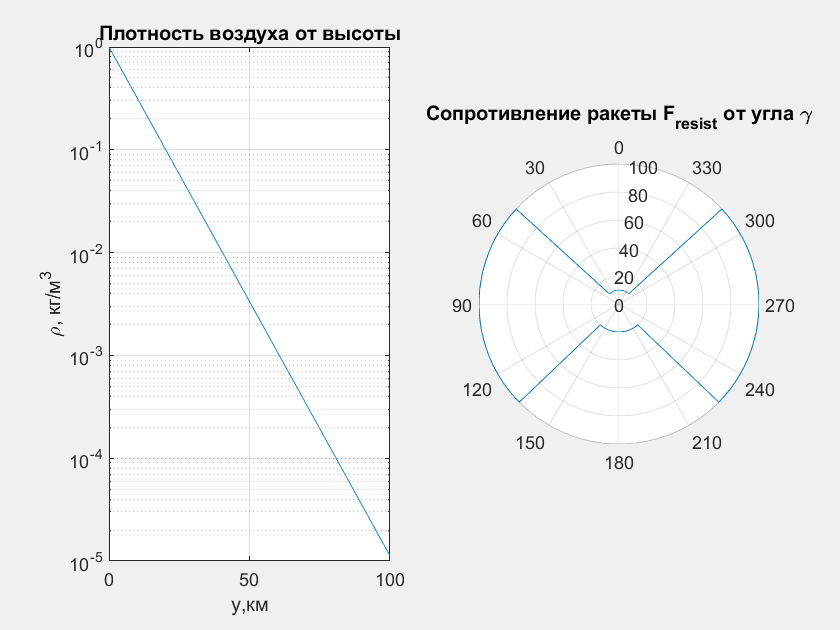

figure('Visible',"on",'NumberTitle','off',"Name",'Физическая модель: Белый')
y = linspace(0,100000);
gamma = linspace(0,2*pi);

subplot(121);
semilogy(y/1e3,airDencity(y));
grid on;
xlabel('y,км');
ylabel('\rho, кг/м^3');
title('Плотность воздуха от высоты');

subplot(122);
polarplot(gamma,abs(resistanceForce(1,1,gamma)));
set(gca,'ThetaZeroLocation','top');
title('Сопротивление ракеты F_{resist} от угла \gamma');

function rho = airDensity(y)
    T = 300;
    R = 8.31;
    M = 0.029;
    g = 9.8;
    rho0 = 1;
    rho = rho0 * exp(-(M*g*y)/(R*T));
    end

function F = resistanceForce(v, rho, gamma)
    gamma(gamma > pi) = 2 * pi - gamma(gamma > pi);

    k = zeros(size(gamma));
    k(gamma <= pi/4) = 1;
    k(gamma > pi/4 & gamma <= 3*pi/4) = 10;
    k(gamma > 3*pi/4) = 2;

    F = -v * norm(v) * k * rho * 10;
    end

    function F_jet = jetForce(mu, vjet)
    F_jet = vjet * mu;
    end